# Examine Bode Plots for Different System Responses

Examine Frequency Response of Transfer Function: 


$$G(s) = \frac{1}{1 + as} \rightarrow\frac{1}{1 + j\omega a}$$


clc; close all; clear;
% First order Frequency Response
s = tf('s');
a = 1;
G = 1/(1 + a*s)

G =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



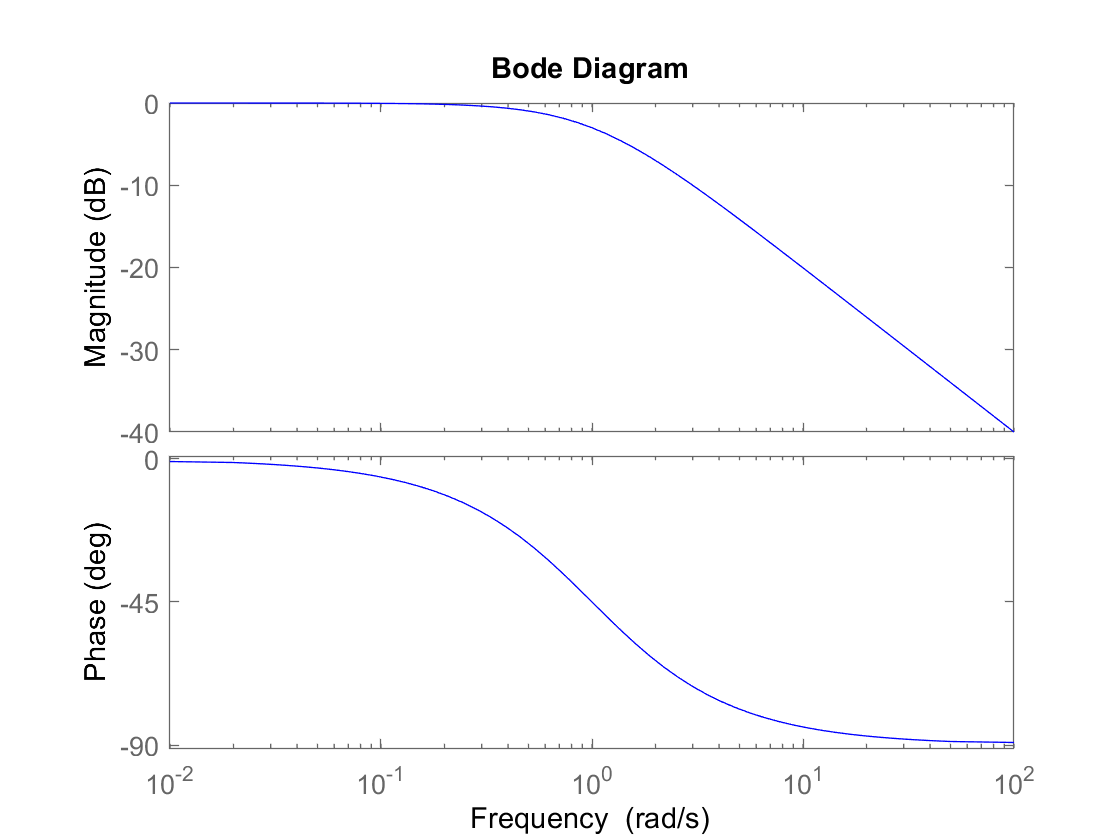

figure, G_bode = bodeplot(G,'b'); 

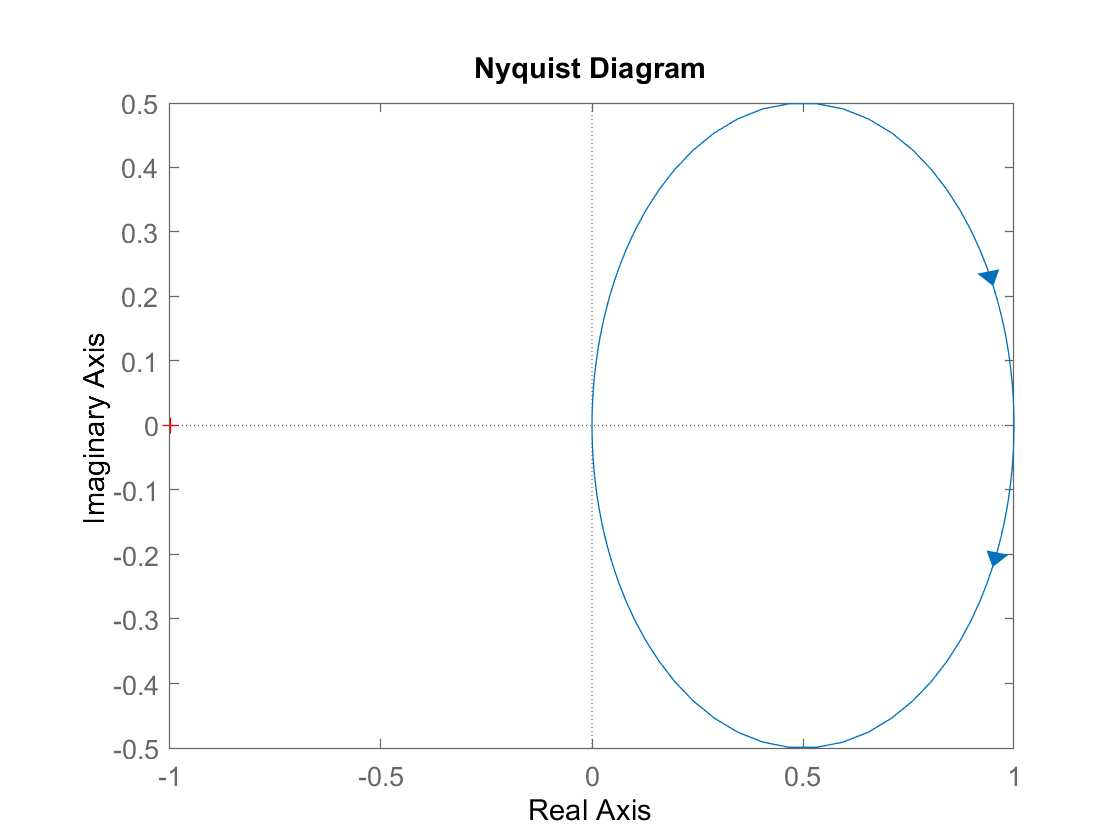

figure, nyquist(G)

Examine Frequency Response of Integrator Controller:


$$G(s) = \frac{1}{bs} \rightarrow\frac{1}{j\omega b}$$


% Integrator Frequency Response
b = 1; Int = 1/(b*s)

Int =
 
  1
  -
  s
 
Continuous-time transfer function.



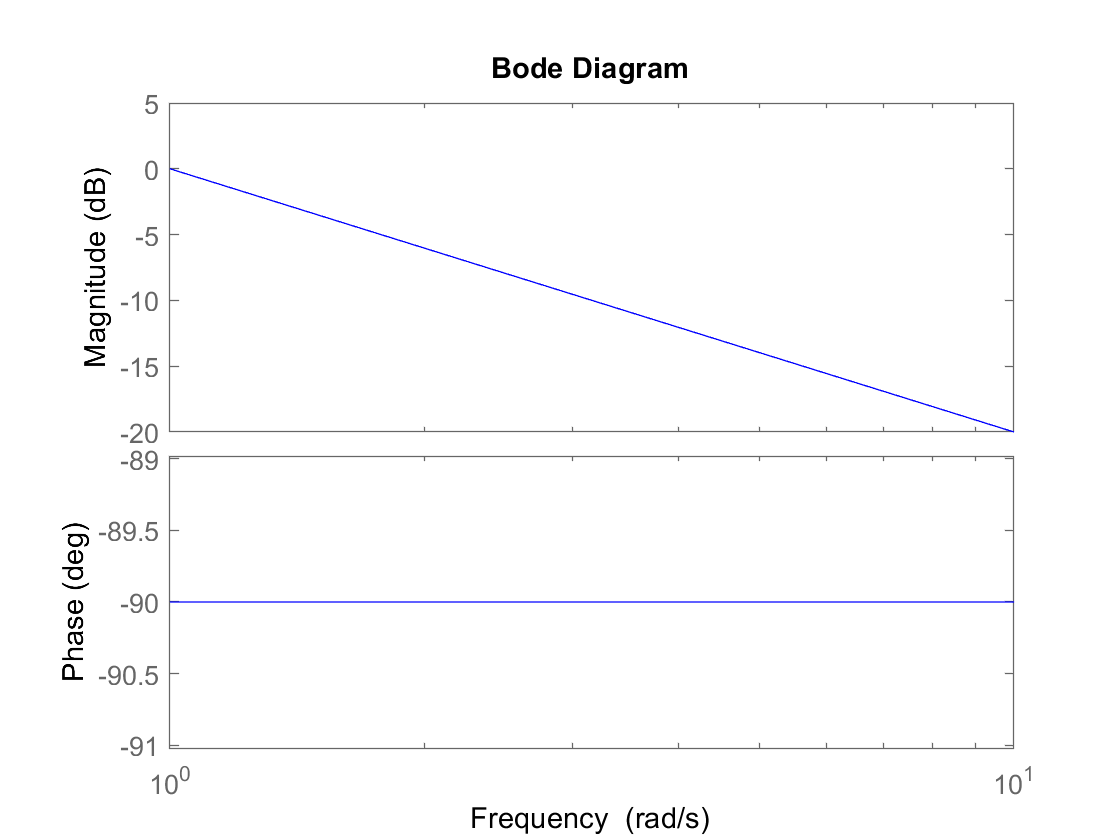

figure, h_i = bodeplot(Int,'b'); 

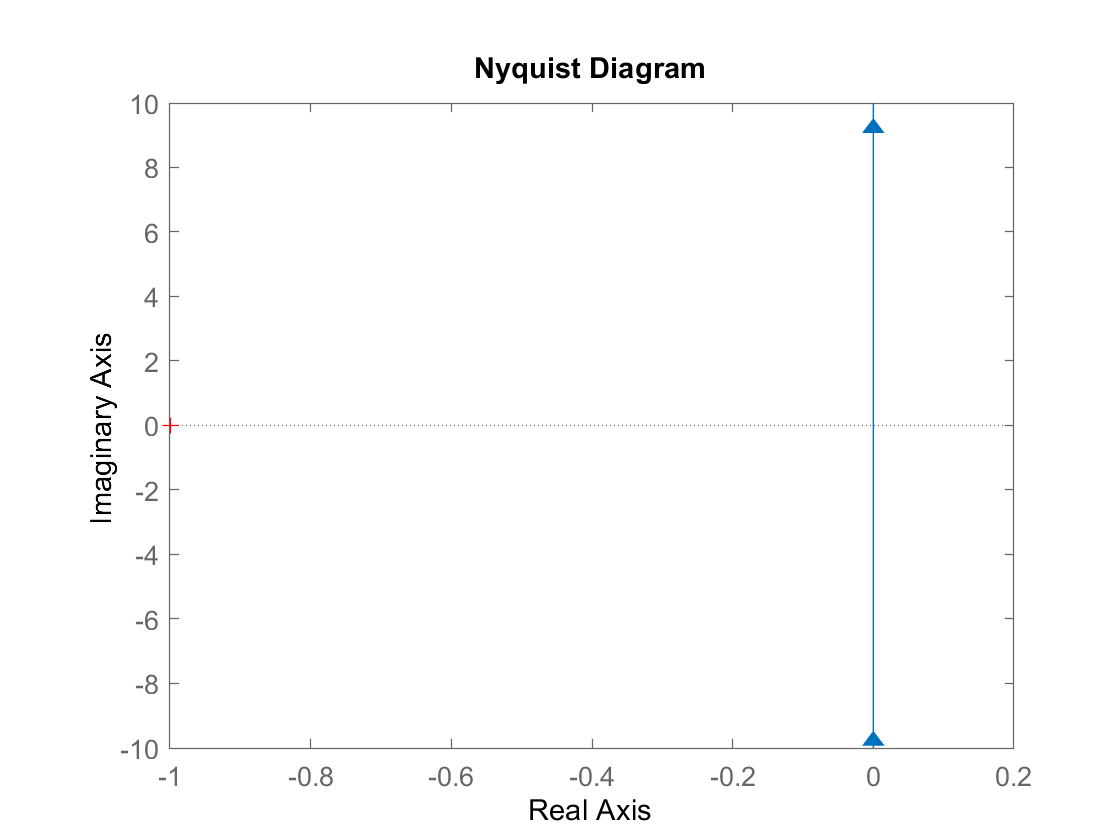

figure, nyquist(Int)

Examine Frequency Reponse of Derivative Controller:


$$G(s) = sc \rightarrow j\omega c$$


% Derivative Frequency Response
c = 1; Deriv = (c*s)

Deriv =
 
  s
 
Continuous-time transfer function.



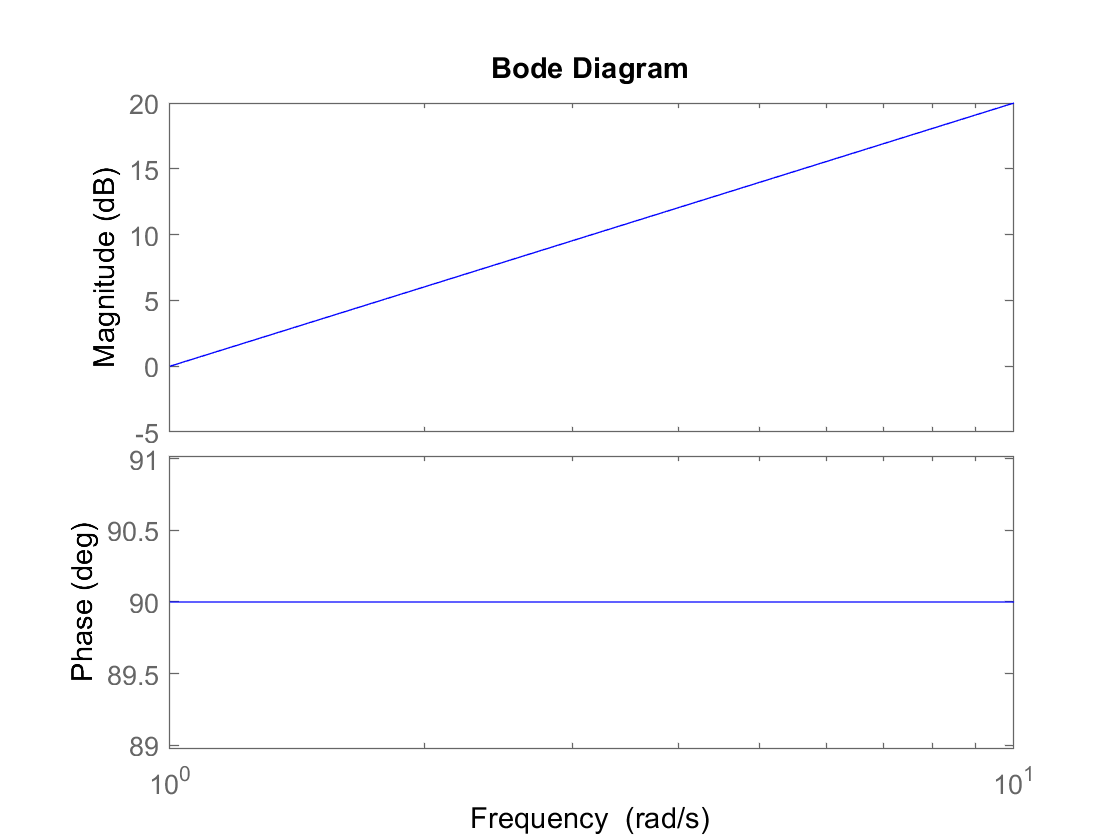

figure, h_d = bodeplot(Deriv,'b'); 

figure, nyquist(Deriv)

Examine Frequency Response of Zero:


$$G(s) = 1 + sd \rightarrow 1 + j\omega d$$


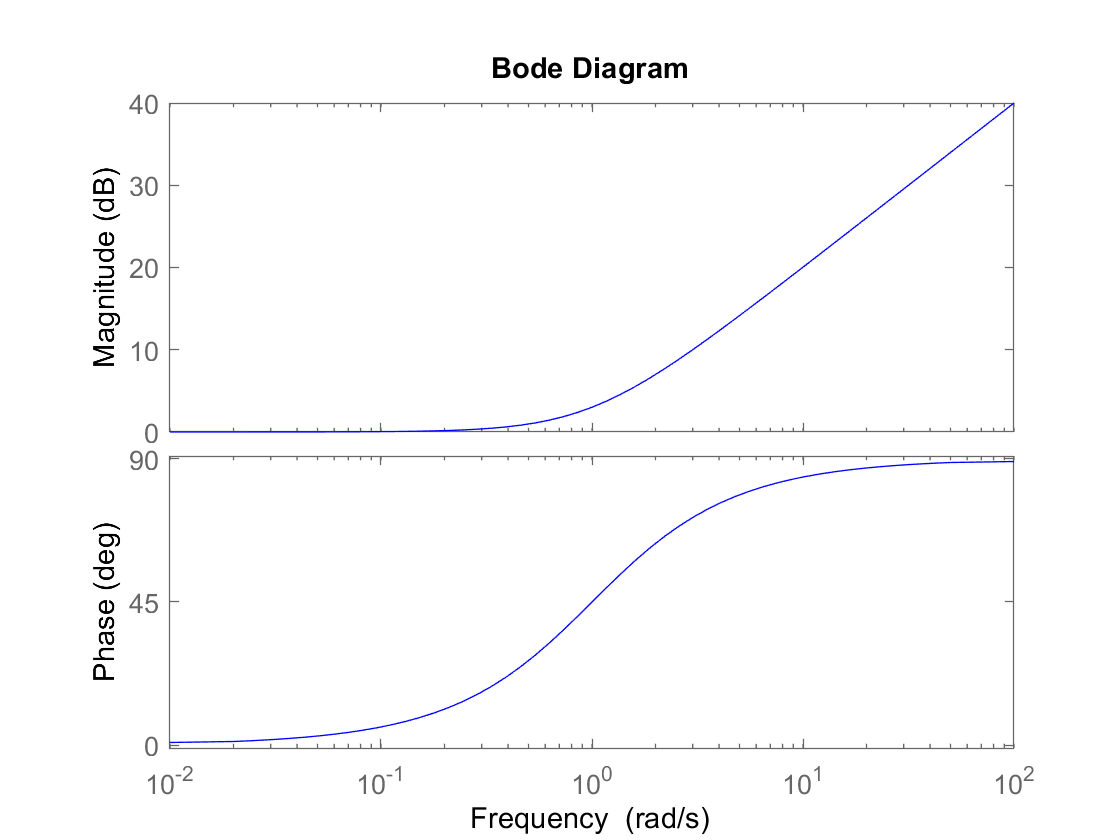

% Single Zero Frequency Response
d = 1; 
G1 = 1 + d*s;
figure, h_g1 = bodeplot(G1,'b'); 

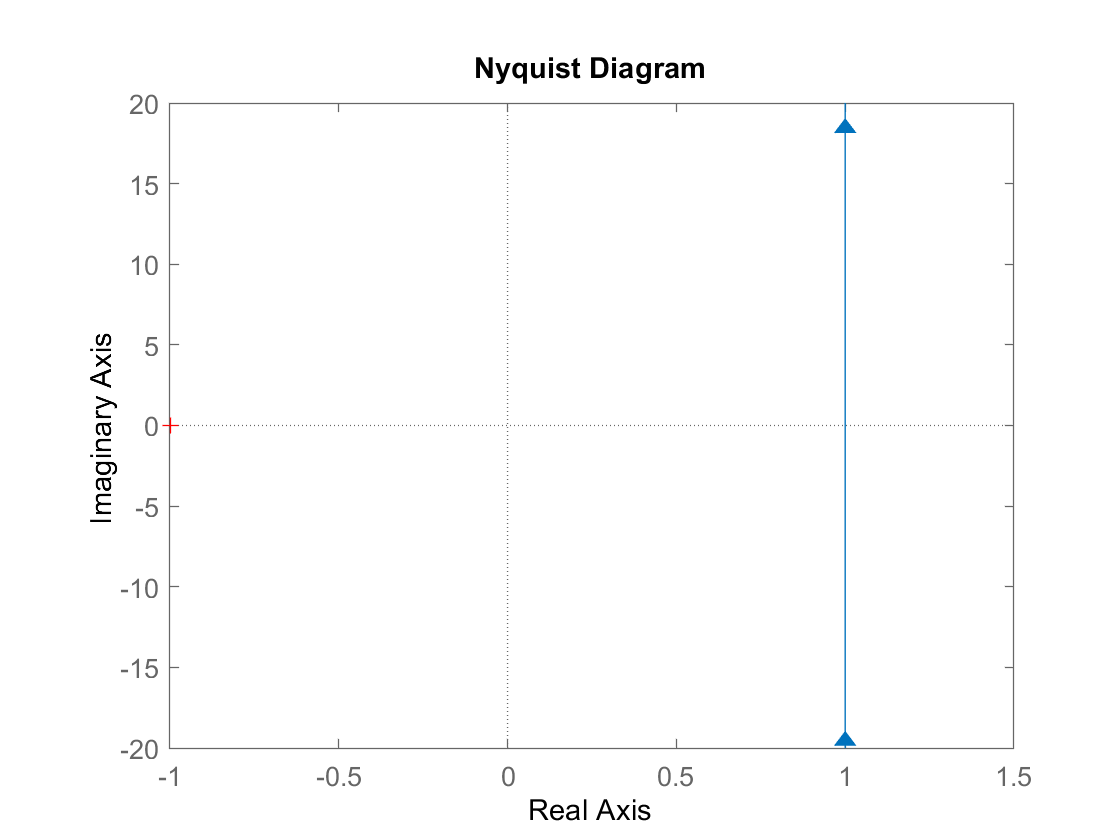

figure, nyquist(G1)

Examine the Frequency Response of Complex Pole:


$$G(s) = \frac{1}{s+a+jb}\rightarrow\frac{1}{a + j(\omega+b)$$


% Single Complex Pole Frequency Response
a = 0.5; b = 4.5;
G2 = 1/(s + a + 1i*b)

G2 =
 
        1
  --------------
  s + (0.5+4.5i)
 
Continuous-time transfer function.



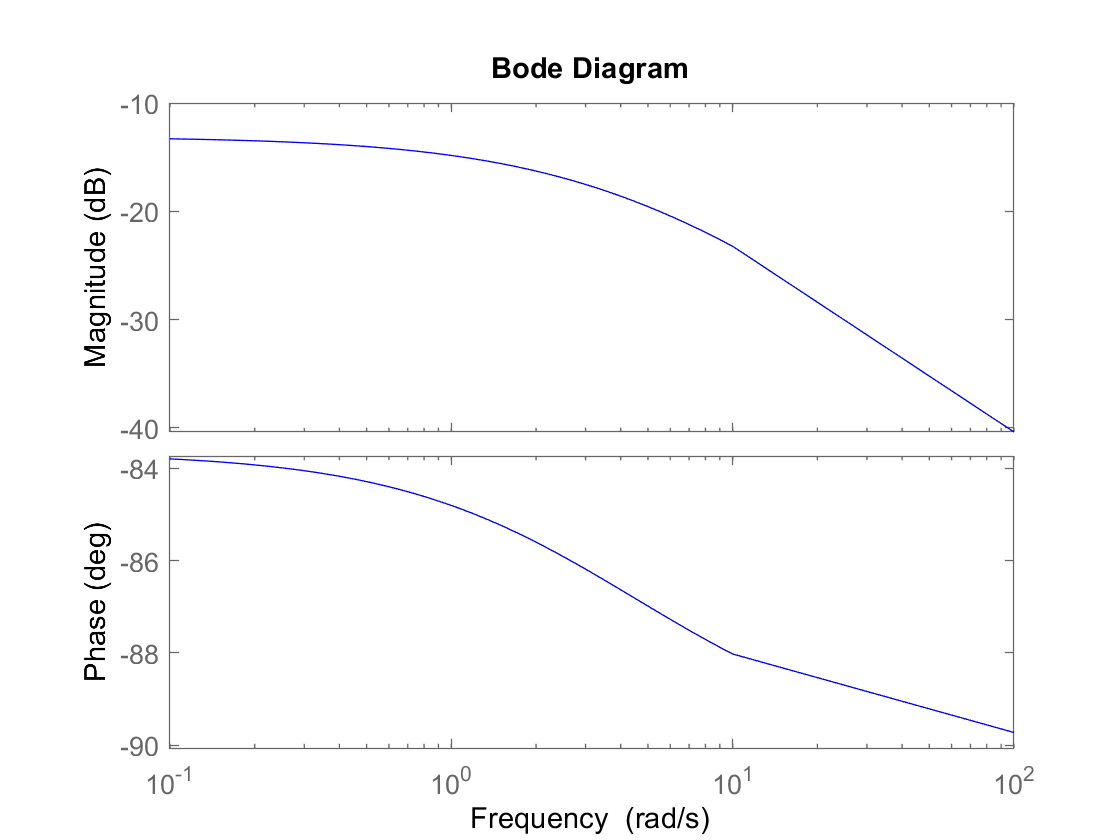

figure, h_g2 = bodeplot(G2,'b'); 

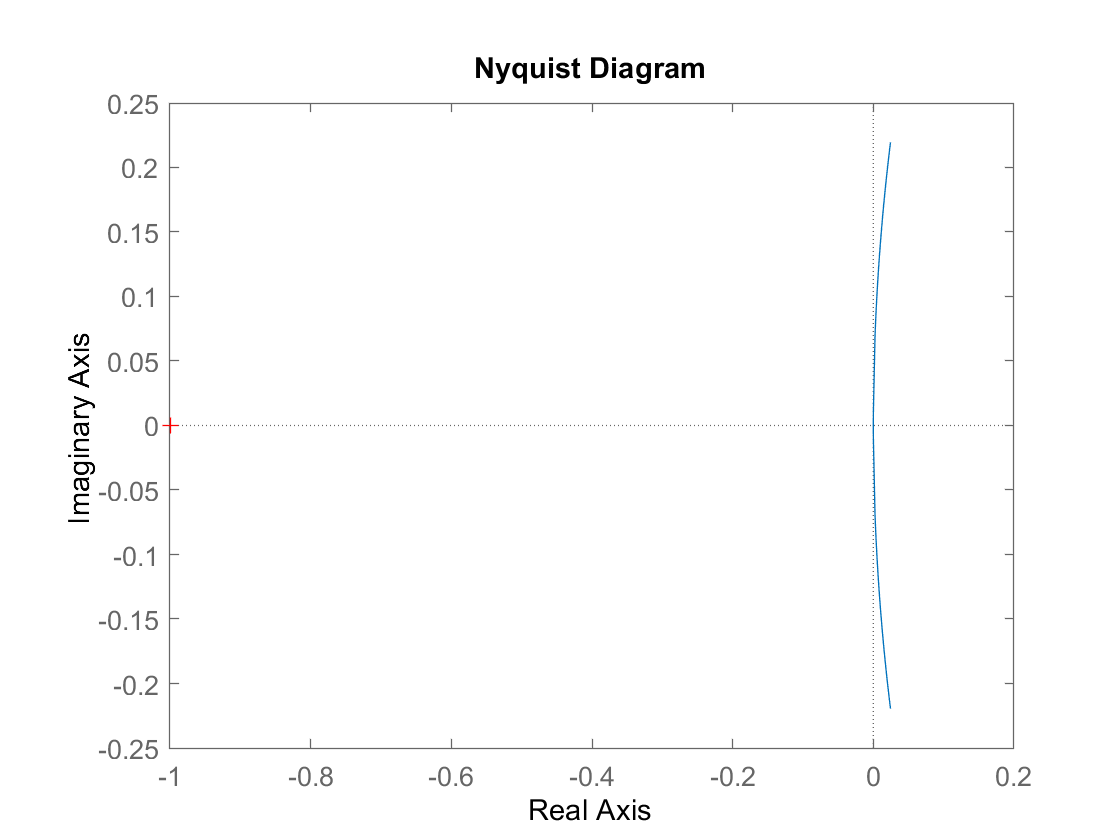

figure, nyquist(G2)

Examine the Frequency Response of Two Complex Poles:


$$G(s) = \frac{1}{s^2 +2as+a^2+b^2} \rightarrow \frac{1}{(j\omega)^2 + 2aj\omega + a^2 + b^2)}$$


% Two Complex Pole Frequency Response
G3 = 1/(s^2 + 2*a*s + a^2 + b^2)

G3 =
 
        1
  --------------
  s^2 + s + 20.5
 
Continuous-time transfer function.



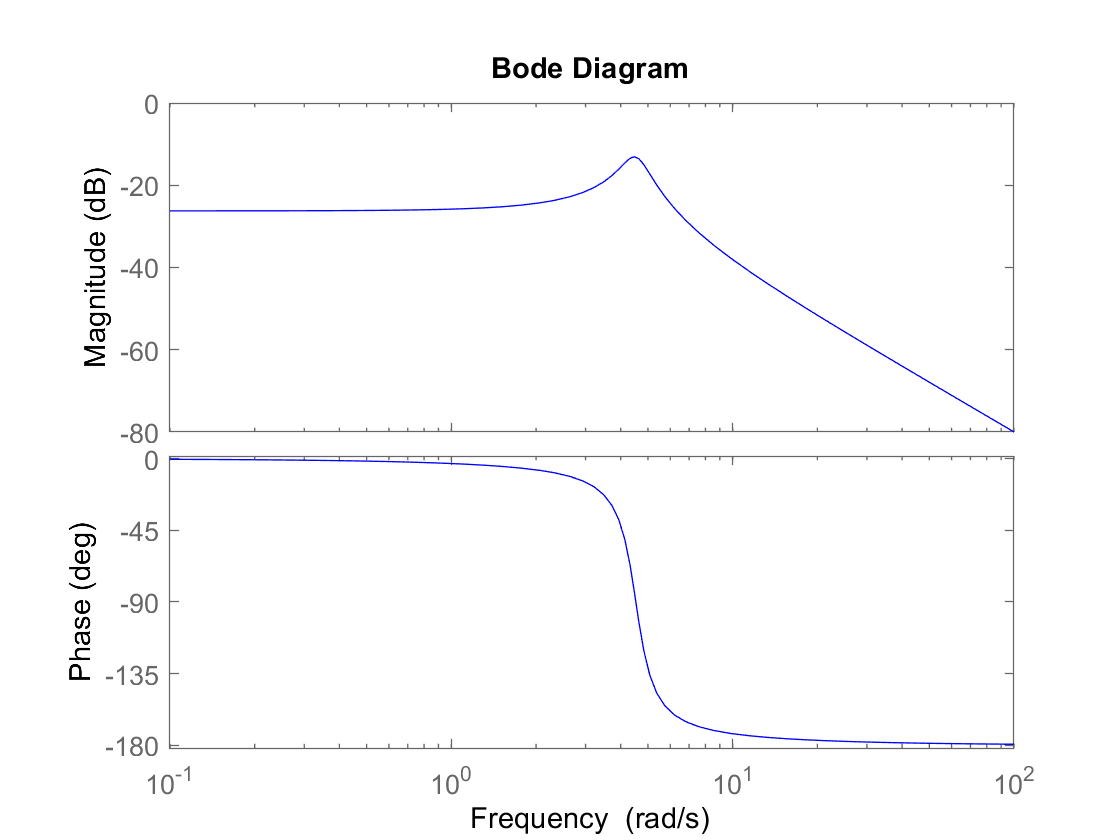

figure, h_g3 = bodeplot(G3,'b'); 

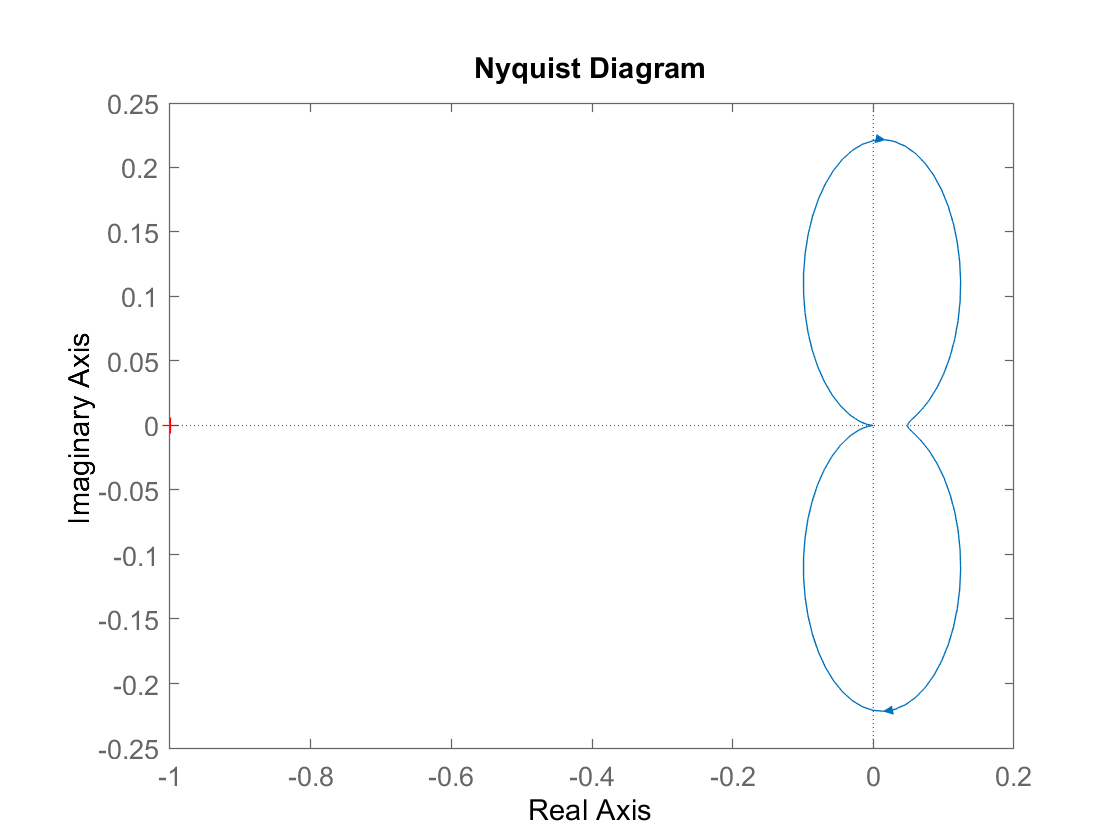

figure, nyquist(G3)

## Unit Delay 


$$u(t) \leftrightarrow u(t - T)$$


s = tf('s');
U = 1/s

U =
 
  1
  -
  s
 
Continuous-time transfer function.



T = 5; shift = exp(-s*T)

shift =
 
  exp(-5*s) * (1)
 
Continuous-time transfer function.



Taking the Laplace Transform of the Unit Delay, we get:


$$L\{u(t-T)\} = e^{-sT}U(s)$$


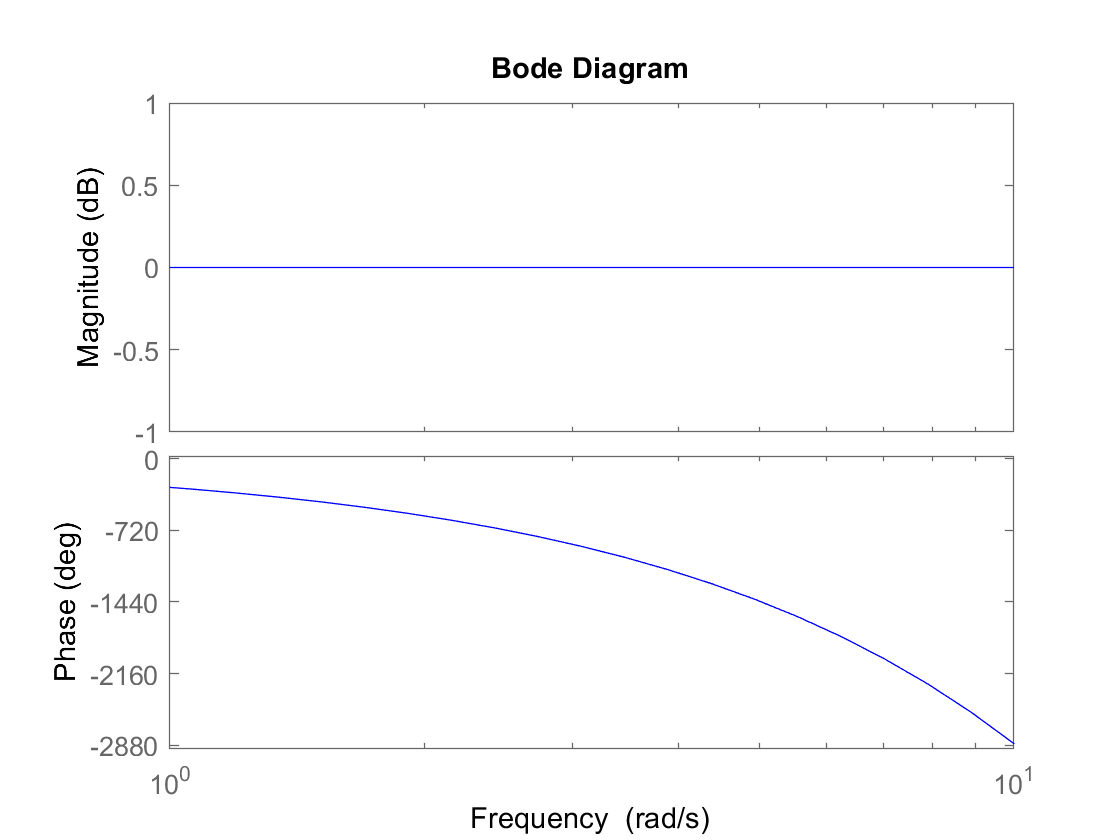

figure, h_shift = bodeplot(shift,'b'); 

Us = U*shift

Us =
 
              1
  exp(-5*s) * -
              s
 
Continuous-time transfer function.



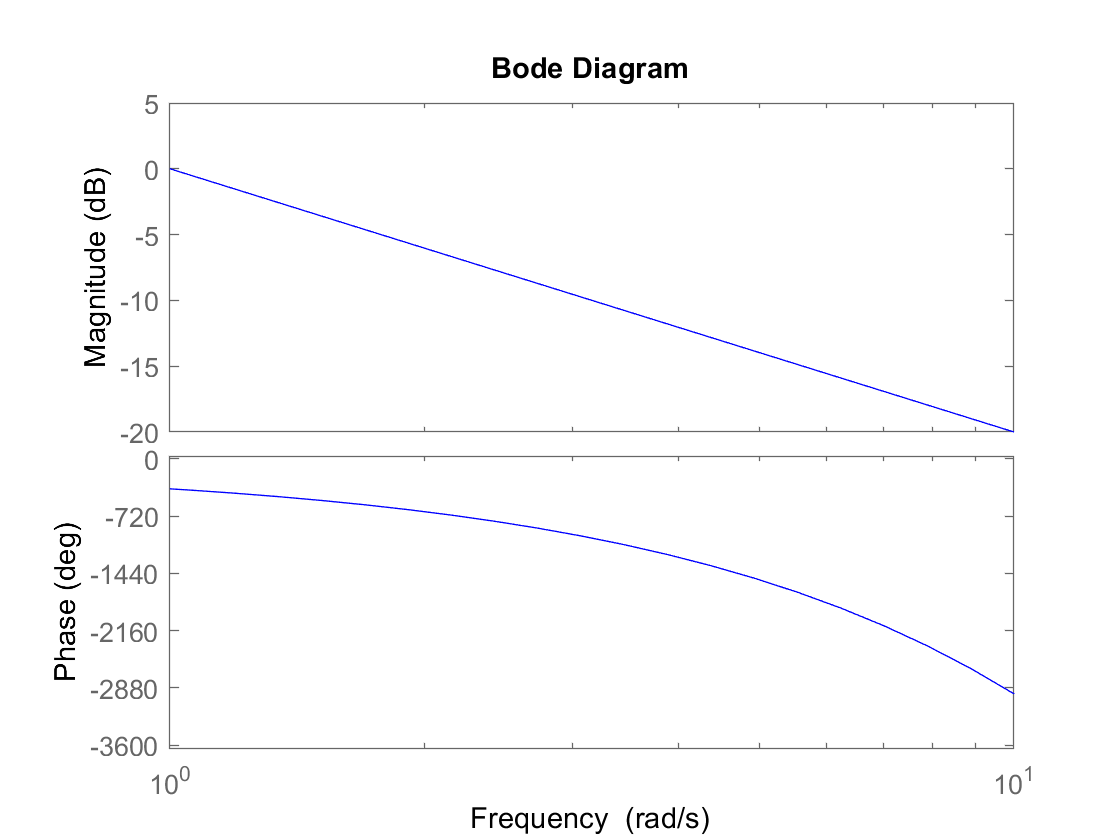

figure, h_U = bodeplot(Us,'b'); 

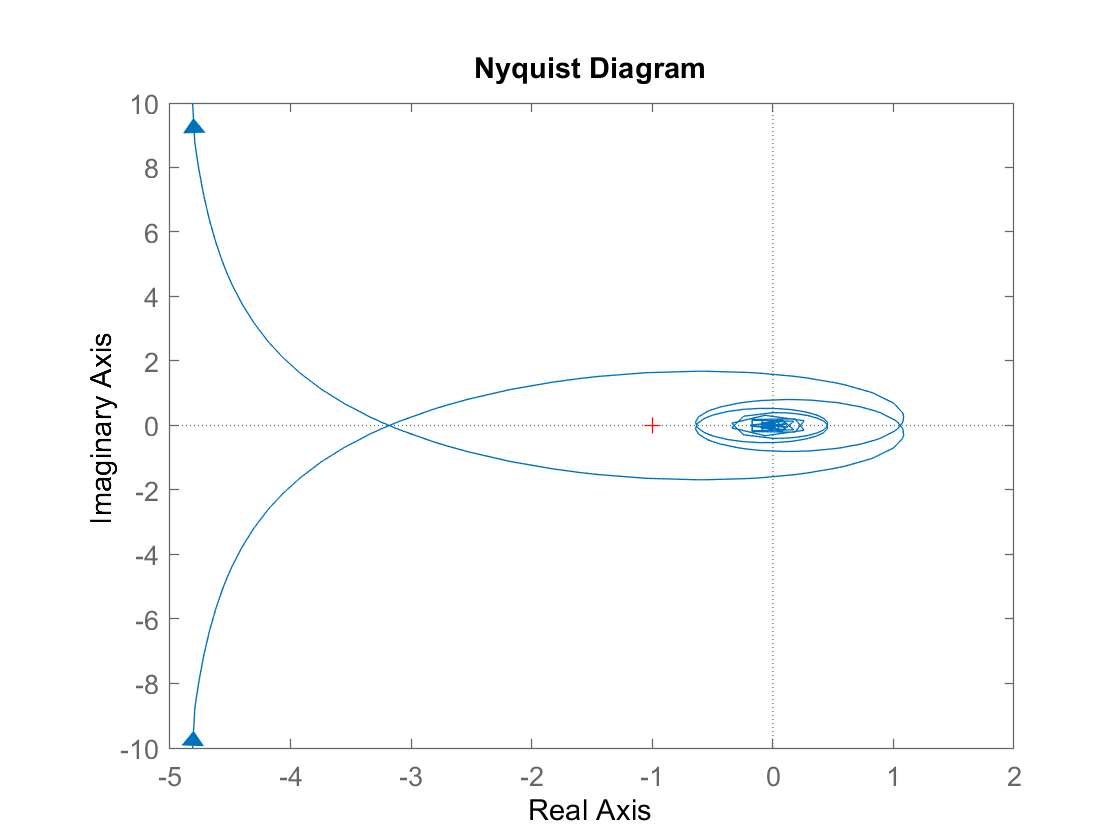

figure, nyquist(Us)

Next we define our next system, $F(s)$ as:


$$F(s) = \frac{k}{1 + s}$$


k = 100; Fs = k/(1 + s)

Fs =
 
   100
  -----
  s + 1
 
Continuous-time transfer function.



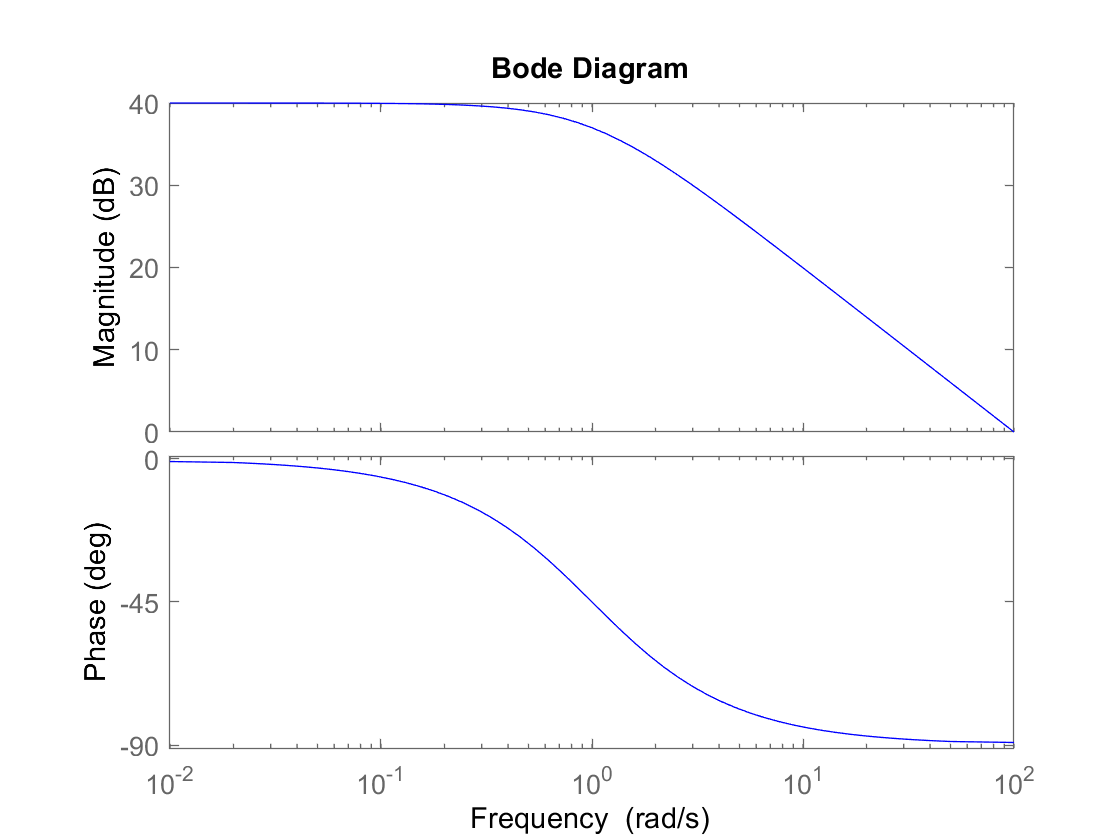

figure, h_F = bodeplot(Fs,'b'); 

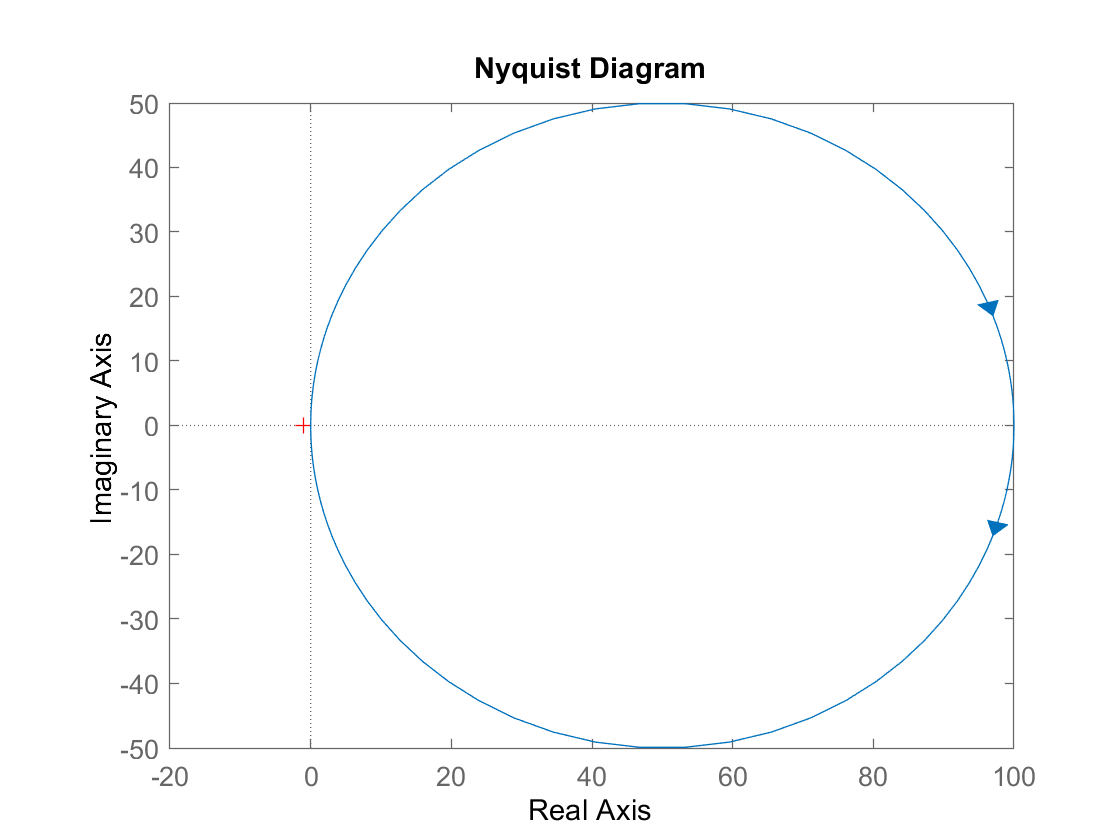

figure, nyquist(Fs)

Then the output, $Y(s)$ is the product of $Y(s) = e^{-sT}U(s)*F(s)$


$$Y(s) = \frac{100e^{-5j\omega}}{s^2 + s}$$


Ys = Us*Fs

Ys =
 
                100
  exp(-5*s) * -------
              s^2 + s
 
Continuous-time transfer function.



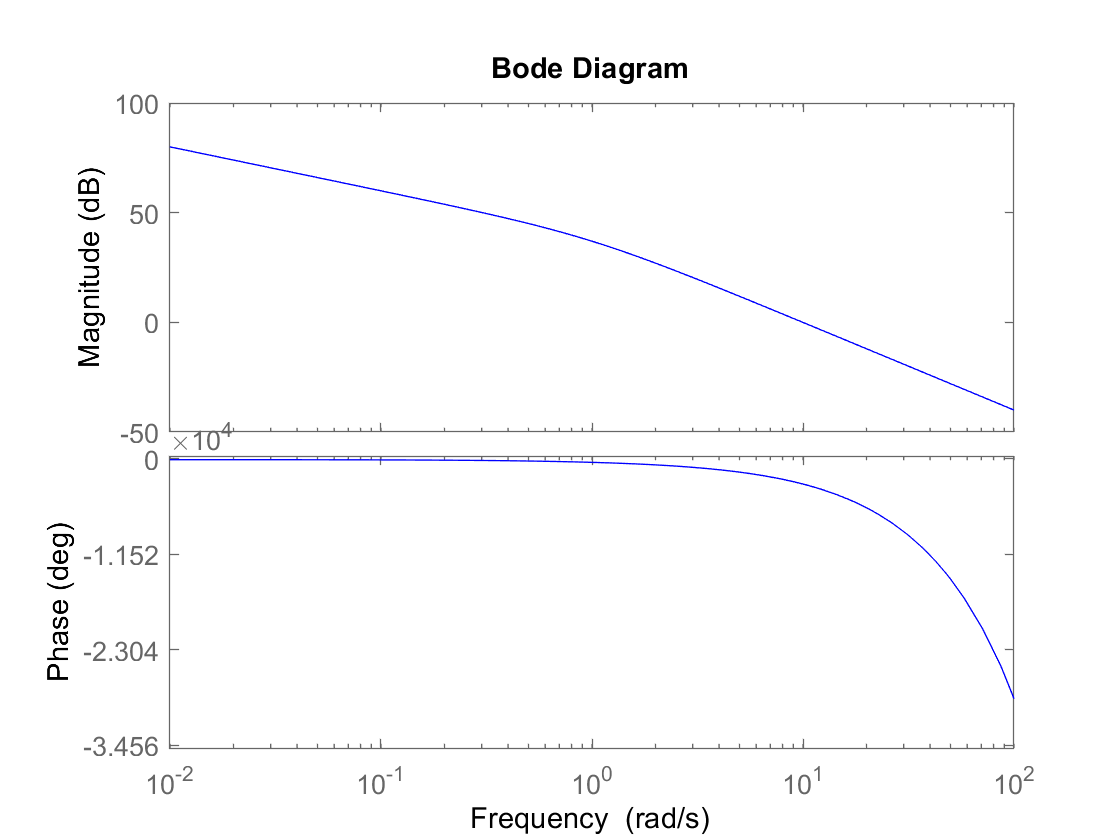

figure, h_Ys = bodeplot(Ys,'b'); 

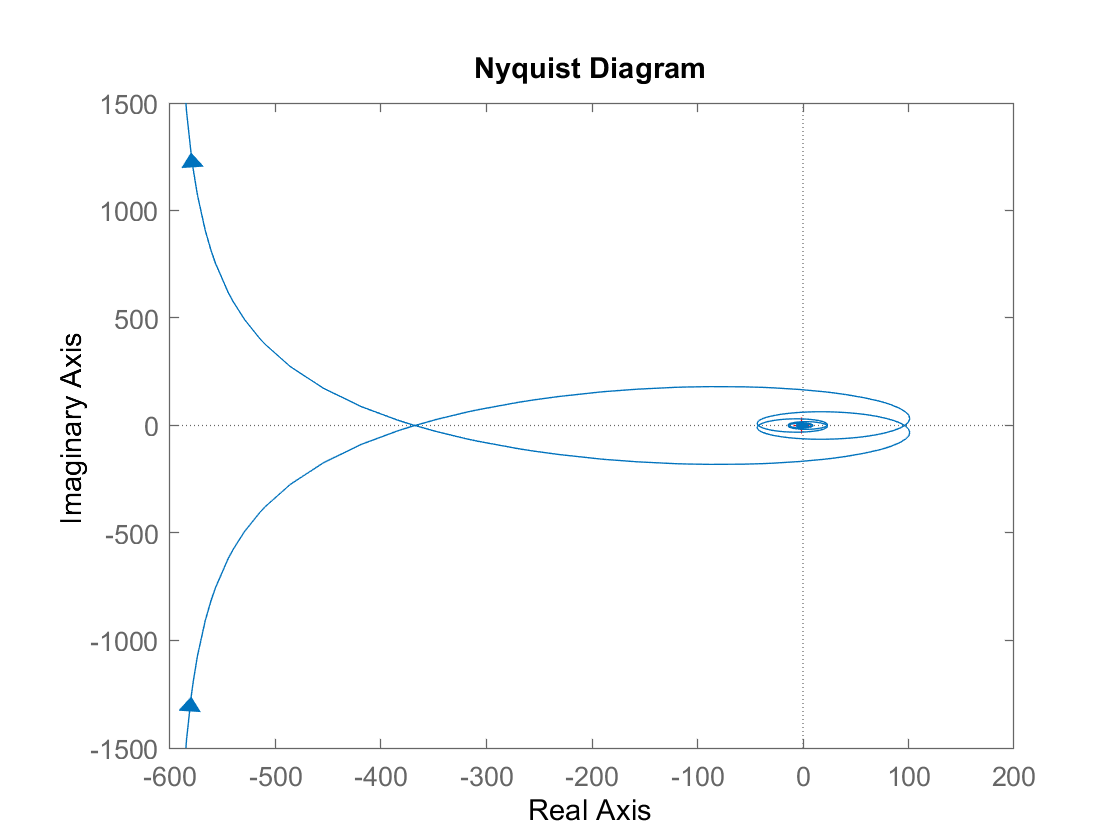

figure, nyquist(Ys)